# LAB 3 - Bo Chang Lin - MAT 275

# Exercise 1

### **Part (a)**

***NOTE****: We often define the right-hand side of an ODE as some function, say *$f$*, in terms of the input and output variables in the ODE. For example, *$\frac{\textrm{dy}}{\textrm{dt}}=f\left(t,y\right)=3\ldotp 25y\ldotp$* Although the ODE does not explicitly depend on *$t$*, it does so implicitly, since *$y$* is a function of *$t$*. Therefore, *$t$* is an input variable of *$f$*.* 

Define ODE function $f$for your version of the lab.


$$\frac{\mathrm{dy}}{\mathrm{dt}}=\frac{1}{2}y$$


f = @(t,y) 0.5*y;

Define vector $t$ of time-values over the interval in your version of the lab, to compute analytical solution vector.

t = linspace(0,1.8,100); 

Create vector of analytical solution values at corresponding t values.


$$y=-4e^{0\ldotp 5t}$$


y = -4*exp(0.5*t);

Solve IVP numerically using forward Euler's method with Nsmall timesteps (use variable names as instructed).

[t9,y9] = euler(f,[0,1.8],-4,9);  % solve the ODE using Euler's 9 steps

Solve IVP numerically using forward Euler's method with Nmed timesteps (use variable names as instructed).

[t90,y90] = euler(f,[0,1.8],-4,90);  % solve the ODE using Euler's 90 steps

Solve IVP numerically using forward Euler's method with Nlarge timesteps (use variable names as instructed).

[t900,y900] = euler(f,[0,1.8],-4,900);  % solve the ODE using Euler's 900 steps

Solve IVP numerically using forward Euler's method with Nhuge timesteps (use variable names as instructed).

[t9000,y9000] = euler(f,[0,1.8],-4,9000);  % solve the ODE using Euler's 9000 steps

**In the following steps, we define error as exact - numerical solution value at the last time step**

Compute numerical solution error at the last time step for forward Euler with Nsmall timesteps (use variable names as instructed).

e9 = y(end) - y9(end);       % error when N = 9

Compute numerical solution error at the last time step for forward Euler with Nmed timesteps (use variable names as instructed).

e90 = y(end) - y90(end);     % error when N = 90

Compute numerical solution error at the last time step for forward Euler with Nlarge timesteps (use variable names as instructed).

e900 = y(end) - y900(end);   % error when N = 900

Compute numerical solution error at the last time step for forward Euler with Nhuge timesteps (use variable names as instructed).

e9000 = y(end) - y9000(end); % error when N = 9000

Compute ratio of errors between N=Nsmall and N=Nmed. 

ratio1 = e9/e90;

Compute ratio of errors between N=Nmed and N=Nlarge.

ratio2 = e90/e900;

Compute ratio of errors between N=Nlarge and N=Nhuge. 

ratio3 = e900/e9000;

### **FILL OUT THE TABLE BELOW **

format short
n_steps = [9;90;900;9000];
approximation = [y9(end);y90(end);y900(end);y9000(end)];
error = [e9;e90;e900;e9000];
ratio = {'N/A';ratio1;ratio2;ratio3};
T1 = table(n_steps,approximation,error,ratio)

T1 = 4×4 table
    n_steps    approximation       error         ratio   
    _______    _____________    ___________    __________

        9         -9.4318          -0.40662    {'N/A'   }
       90         -9.7945         -0.043882    {[9.2663]}
      900          -9.834        -0.0044233    {[9.9205]}
     9000          -9.838       -0.00044269    {[9.9920]}


disp(y(end)) % Actual value

   -9.8384



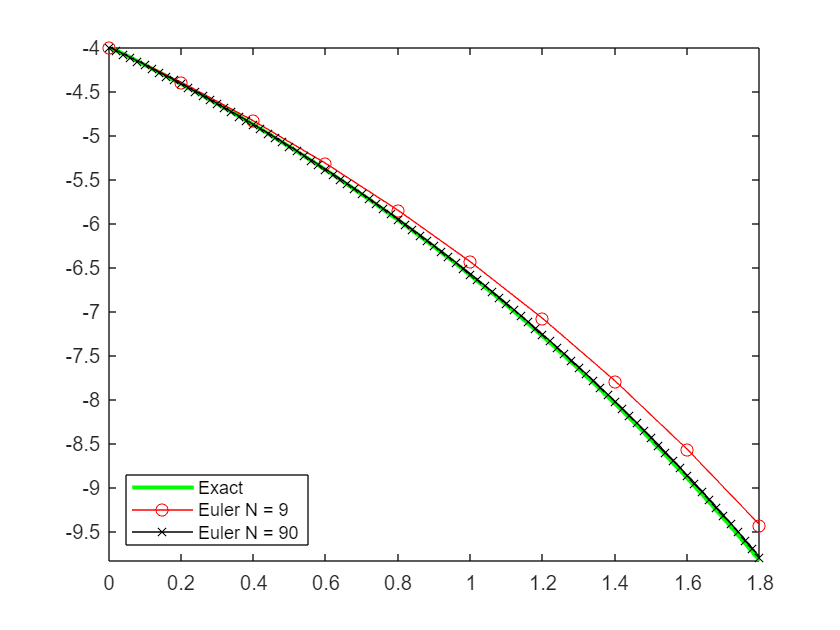

% Supplementary figure
figure(1)
plot(t,y,'g-',LineWidth=2)
hold on
plot(t9,y9,'ro -',t90,y90,'kx -')
legend('Exact','Euler N = 9','Euler N = 90','location','best')
axis tight
hold off

### **Part (b)**

T1(:,[1 4])

ans = 4×2 table
    n_steps      ratio   
    _______    __________

        9      {'N/A'   }
       90      {[9.2663]}
      900      {[9.9205]}
     9000      {[9.9920]}


**Evidently, the ratio approaches 10 and coincides with the n_steps increment ratio, which conform the fact that Euler's method is a “first-order" method.**

### **Part (c)**

**Euler's method overestimates the solution y because the tangent line is a linear approximation of the solution curve. The solution curve is typically curved, so the tangent line will overestimate the slope of the curve at most points. This means that the Euler approximation will step too far along the tangent line, resulting in an overestimate of y.**

**However, there are some cases where Euler's method can underestimate the solution y For example, if the solution curve is concave up and the step size is large, then Euler's method may underestimate the slope of the solution curve. This can result in an underestimate of y.**

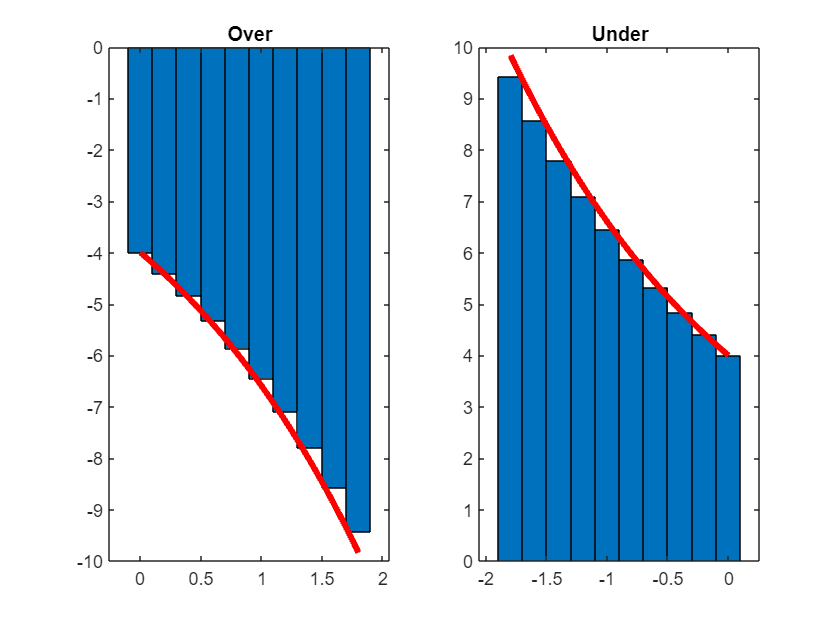

% Supplementary figure
figure(2)
subplot(1,2,1)
bar(t9,y9,BarWidth=1)
hold on
plot(t,y,'r-',LineWidth=3)
title('Over')

subplot(1,2,2)
bar(-t9,-y9,BarWidth=1)
hold on
plot(-t,-y,'r-',LineWidth=3)
title('Under')
hold off

# Exercise 2


$$\frac{\textrm{dy}}{\textrm{dt}}=-2\ldotp 8y\;\;;y\left(0\right)=1$$


With solution:


$$y=e^{-2\ldotp 8t}$$


### Part (a)

Plot slopefield for the new ODE  using the given commands. 

t = 0:0.4:6;                 % define a grid in t & y directions
y = -12:2.1:9;

[T,Y] = meshgrid(t,y);       % create 2d matrices of points in ty - plane
dT = ones(size(T));          % dt =1 for all points
dY = -2.8*Y;                 % dy = -2.8*y; this is the ODE
quiver (T,Y,dT,dY)           % draw arrows (t,y)->(t+dt , t+dy)
axis tight                   % adjust look
hold on

### Part (b)

Define vector t of time-values over the given interval to define analytical solution vector.

t = linspace(0,6,100);

Create vector of analytical solution values at corresponding t values.

% y=exp(-2.8*t);
syms y(a)
ode = diff(y) == -2.8*y;
cond = y(0) == 1;
ySol(a) = dsolve(ode,cond);
y=ySol(t);

**NOTE**: *The "hold on" command in the segment of code to plot the slope field indicates to MATLAB to add future plots to the same window unless otherwise specified using the "hold off" command.*

Plot analytical solution vector with slopefield from (a). 

plot(t,y,'k-','linewidth',2)

### Part (c)

***NOTE:**** Recall we can define the right-hand side of an ODE as some function *$f$* . In the case of a one-dimensional autonomous ODE, we may define *$f$*such that *$\frac{\textrm{dy}}{\textrm{dt}}=f\left(t,y\right)$

Define ODE function.

f = @(t,y) -2.8*y;

Compute numerical solution to IVP with N timesteps using forward Euler.

[t7,y7] = euler(f,[0 ,6],1,7);

Plot numerical solution with analytical solution from (b) and slopefield from (a) using circles to distinguish between the approximated data (i.e., the numerical solution values) and actual (analytical) solution.

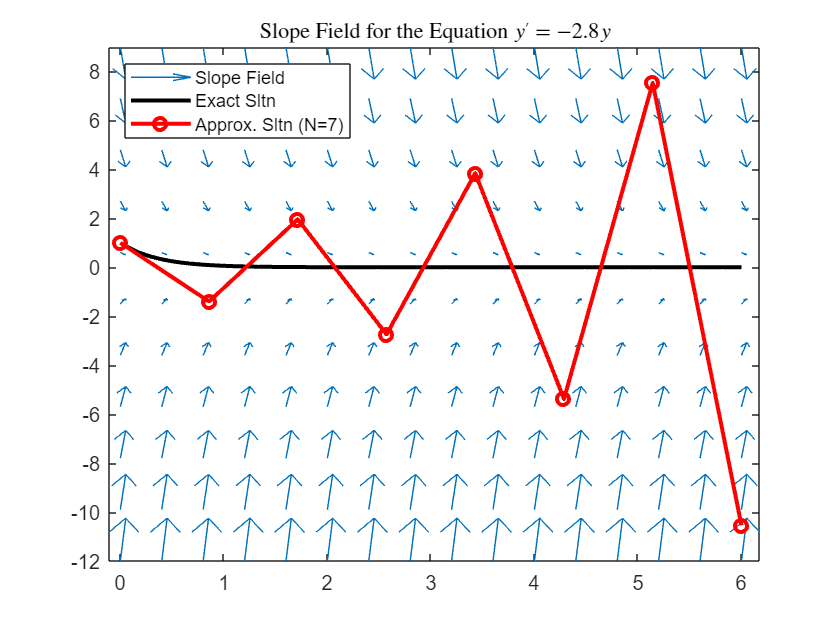

plot(t7,y7,'ro-','linewidth',2)
legend('Slope Field','Exact Sltn','Approx. Sltn (N=7)','location','northwest');
title("Slope Field for the Equation $y'=-2.8y$","Interpreter","latex")
hold off   % end plotting in this figure window

**I believe the cause of such deviations is the accumulated errors due to the algorithm. Especially when the given function has negative slope rates, this could lead to alternate sign and seems to be divergent under certain threshold in my opinion. **

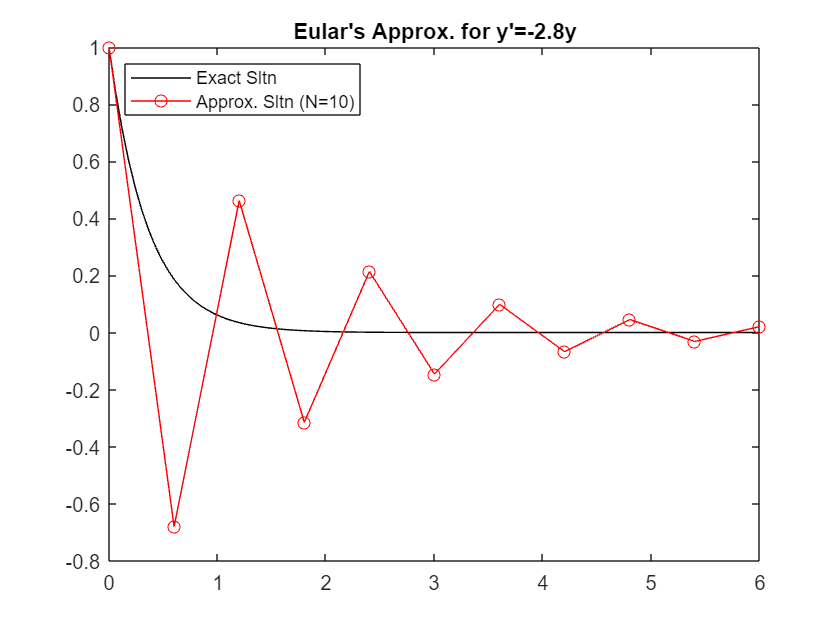

% Supplementary figure wiht slider control for changing N-steps
figure(4)
k=10;  % Slider control N-steps N=k (set 6<=k<=30)
y = exp(-2.8*t);
f = @(t,y) -2.8*y;
[Tk,Yk]=euler(f,[0 ,6],1,k);
plot(t,y,'k-',Tk,Yk,'ro-')
legend('Exact Sltn',strcat('Approx. Sltn (N=',num2str(k),')'),'location','northwest');
title("Eular's Approx. for y'=-2.8y")

### Part (d)

 Define new grid of t and y values at which to plot vectors for slope field.

t = 0:0.4:6;                 
y = -0.6:0.2:1.3;         

Plot slope field corresponding to the new grid.

[T,Y] = meshgrid(t,y);       % create 2d matrices of points in ty - plane
dT = ones(size(T));          % dt =1 for all points
dY = -2.8*Y;                 % dy = -2.8*y; this is the ODE
figure
quiver (T,Y,dT,dY)           % draw arrows (t,y)->(t+dt , t+dy)
axis tight                   % adjust look
hold on

Define vector t of time-values over the given interval to define analytical soution vector.

t = linspace(0,6,100);

Create vector of analytical solution values at corresponding t values.

y = exp(-2.8*t);

Define ODE function.

f = @(t,y) -2.8*y;

Compute numerical solution to IVP with the given timesteps using forward Euler. 

[t14,y14] = euler(f,[0 ,6],1,14);

plot numerical solution together with slope field and analytical solution

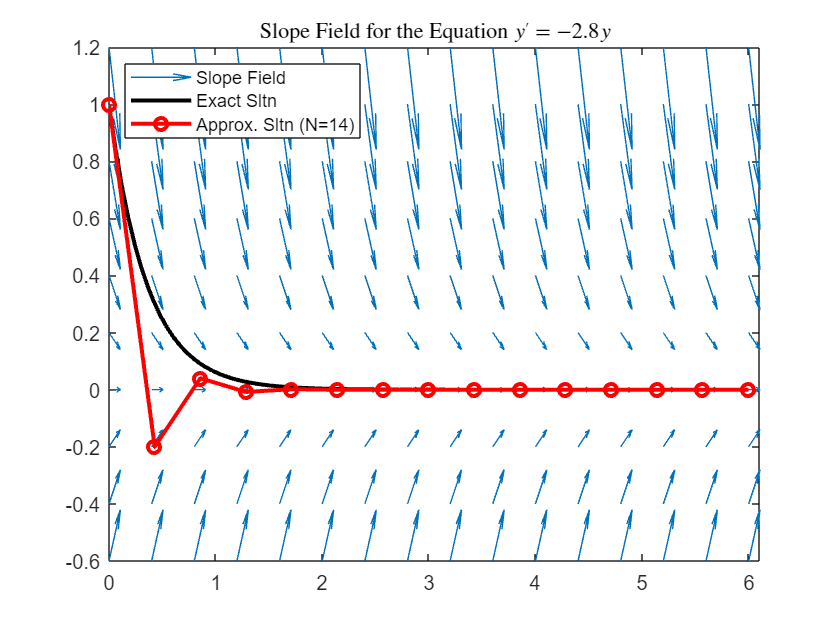

plot(t,y,'k-',t14,y14,'ro-','linewidth',2)
legend('Slope Field','Exact Sltn','Approx. Sltn (N=14)','location','northwest');
title("Slope Field for the Equation $y'=-2.8y$","Interpreter","latex")
hold off   

**Evidently, the red line representing the approximation coincides with the direction field at each turning point.**

# Exercise 3

Display contents of impeuler M-file.

type 'impeuler.m'

 function [t,y] = impeuler(f,tspan,y0,N)

% Modified codes from euler.m

m = length(y0);
t0 = tspan(1);
tf = tspan(2);
h = (tf-t0)/N;             
t = linspace(t0,tf,N+1);    
y = zeros(m,N+1);   
y(:,1) = y0';             
for n=1:N
    f1 = f(t(n),y(:,n));
    f2 = f(t(n)+h,y(:,n)+h*f1);
    y(:,n+1) = y(:,n) + 0.5*h*(f1+f2);   
end
t = t'; y = y';    
end


Define ODE function. 

f = @(t,y) 0.5* y;

Compute numerical solution to IVP with Nsmall timesteps using "improved Euler."

[t9,y9] = impeuler(f,[0 ,1.8],-4,9);
disp([t9 y9])

         0   -4.0000
    0.2000   -4.4200
    0.4000   -4.8841
    0.6000   -5.3969
    0.8000   -5.9636
    1.0000   -6.5898
    1.2000   -7.2817
    1.4000   -8.0463
    1.6000   -8.8912
    1.8000   -9.8247



**Match with the protocol**

# Exercise 4

### **Part (a)**

Define ODE function $f$for your version of the lab.

f = @(t,y) 0.5*y;

Define vector $t$ of time-values over the interval in your version of the lab, to compute analytical solution vector.

t = linspace(0,1.8,100); 

Create vector of analytical solution values at corresponding t values.

y = -4*exp(0.5*t);

Solve IVP numerically using improved Euler's method with Nsmall timesteps (use variable names as instructed).

[ti9,yi9] = impeuler(f,[0 ,1.8],-4,9);

Solve IVP numerically using improved Euler's method with Nmed timesteps (use variable names as instructed).

[ti90,yi90] = impeuler(f,[0 ,1.8],-4,90);

Solve IVP numerically using improved Euler's method with Nlarge timesteps (use variable names as instructed).

[ti900,yi900] = impeuler(f,[0 ,1.8],-4,900);

Solve IVP numerically using improved Euler's method with Nhuge timesteps (use variable names as instructed).

[ti9000,yi9000] = impeuler(f,[0 ,1.8],-4,9000);

In the following steps, we define error as exact - numerical solution value at the last time step

Compute numerical solution error at the last time step for improved Euler with Nsmall timesteps (use variable names as instructed).

ei9 = y(end) - yi9(end);

Compute numerical solution error at the last time step for improved Euler with Nmed timesteps (use variable names as instructed).

ei90 = y(end) - yi90(end); 

Compute numerical solution error at the last time step for improved Euler with Nlarge timesteps (use variable names as instructed).

ei900 = y(end) - yi900(end);

Compute numerical solution error at the last time step for improved Euler with Nhuge timesteps (use variable names as instructed).

ei9000 = y(end) - yi9000(end);

Compute ratio of errors between N=Nsmall and N=Nmed. 

Ratio1 = ei9/ei90;

Compute ratio of errors between N=Nmed and N=Nlarge.

Ratio2 = ei90/ei900;

Compute ratio of errors between N=Nlarge and N=Nhuge. 

Ratio3 = ei900/ei9000;

### **FILL OUT THE TABLE BELOW **

format long
N_steps = [9;90;900;9000];
Approximation = [yi9(end);yi90(end);yi900(end);yi9000(end)];
Error = [ei9;ei90;ei900;ei9000];
Ratio = {'N/A';Ratio1;Ratio2;Ratio3};
T2 = table(N_steps,Approximation,Error,Ratio)

T2 = 4×4 table
    N_steps      Approximation              Error                    Ratio         
    _______    _________________    _____________________    ______________________

        9      -9.82472704654561      -0.0136853980821918    {'N/A'               }
       90      -9.83826597192574    -0.000146472702059697    {[93.433096336368337]}
      900      -9.83841096997243    -1.47465537025937e-06    {[99.326734241597322]}
     9000      -9.83841242987118    -1.47566172614688e-08    {[99.931803077244581]}


### **Part (b)**

T2(:,[1 4])

ans = 4×2 table
    N_steps            Ratio         
    _______    ______________________

        9      {'N/A'               }
       90      {[93.433096336368337]}
      900      {[99.326734241597322]}
     9000      {[99.931803077244581]}


**Evidently, the Ratio approaches 100 and coincides with the the square of N_steps increment ratio, which conform the fact that Euler's method is a “first-order" method.**

# Exercise 5

***NOTE****: Here, we repeat all the steps from exercise 2, except using improved Euler rather than forward Euler. Remember code doc. *

### Part (a)

Plot slopefield for the new ODE  using the given commands. 

t = 0:0.4:6; y = -12:2.1:9;  % define a grid in t & y directions
[T,Y] = meshgrid(t,y);       % create 2d matrices of points in ty - plane
dT = ones(size(T));          % dt =1 for all points
dY = -2.8*Y;                 % dy = -2.8*y; this is the ODE
quiver (T,Y,dT,dY)           % draw arrows (t,y)->(t+dt , t+dy)
axis tight                   % adjust look
hold on

### Part (b)

Define vector t of time-values over the  given interval  to define analytical solution vector.

t = linspace(0,6,100);

Create vector of analytical solution values at corresponding t values.

y = exp(-2.8*t);

Plot analytical solution vector with slopefield from (a). 

plot(t,y,'k-','linewidth',2)

### Part (c)

Define ODE function.

f = @(t,y) -2.8*y;

Compute numerical solution to IVP with N timesteps using improved Euler.

[t7,y7] = impeuler(f,[0 ,6],1,7);

Plot numerical solution with analytical solution from (b) and slopefield from (a) using circles to distinguish between the approximated data (i.e., the numerical solution values) and actual (analytical) solution.

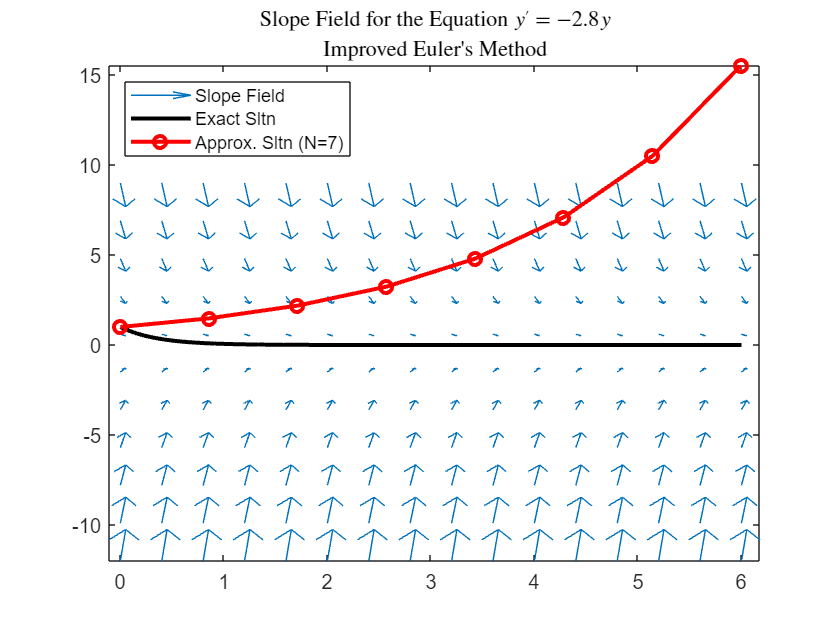

plot(t7,y7,'ro-','linewidth',2)
legend('Slope Field','Exact Sltn','Approx. Sltn (N=7)','location','northwest');
title("Slope Field for the Equation $y'=-2.8y$","Interpreter","latex")
subtitle("Improved Euler's Method","Interpreter","latex") 
hold off

** Under certain threshold of number of step taken, the accumulated errors seems to be divergent.**

### Part (d)

 Define new grid of t and y values at which to plot vectors for slope field.

t = 0:0.4:6;                 
y = -0.6:0.2:1.3;    

Plot slope field  corresponding to the new grid.

[T,Y] = meshgrid(t,y);       % create 2d matrices of points in ty - plane
dT = ones(size(T));          % dt =1 for all points
dY = -2.8*Y;                 % dy = -2.8*y; this is the ODE
quiver (T,Y,dT,dY)           % draw arrows (t,y)->(t+dt , t+dy)
axis tight                   % adjust look
hold on

Define vector t of time-values over the given interval to define analytical soution vector.

t = linspace(0,6,100);

Create vector of analytical solution values at corresponding t values.

y = exp(-2.8*t);

Define ODE function.

f = @(t,y) -2.8*y;

Compute numerical solution to IVP with the given timesteps using improved Euler. 

[t14,y14] = impeuler(f,[0 ,6],1,14);

Plot numerical solution together with slope field and analytical solution

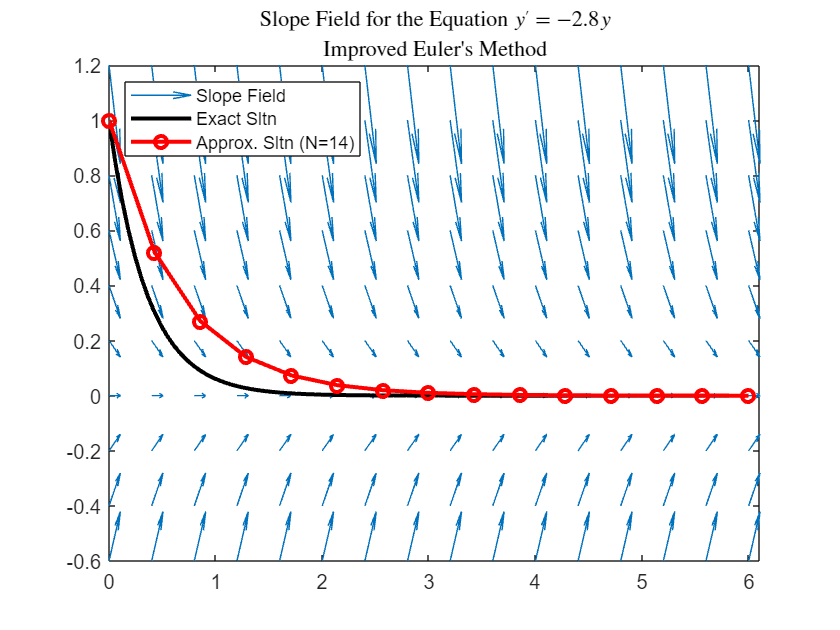

plot(t,y,'k-',t14,y14,'ro-','linewidth',2)
legend('Slope Field','Exact Sltn','Approx. Sltn (N=14)','location','northwest');
title("Slope Field for the Equation $y'=-2.8y$","Interpreter","latex")
subtitle("Improved Euler's Method","Interpreter","latex") 
hold off

**Evidently, the red line representing the approximation coincides with the average of direction field between each two turning points.**